clear; clc;

seed_varieties = ["zd958"];   %% " ", "jd20", "nh816", "jh5"
file_names = [150];

for index1 = 1:length(seed_varieties)
    
    seed_variety = seed_varieties(index1);
    
    for index2 = 1:length(file_names)
        
        file_name = file_names(index2);
        
        tic
        Pre = pretreatment(seed_variety, file_name);
        toc
        
        mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_Pre'));
        save(mat_name, 'Pre');
        eval([mat_name, '= Pre;']) 
        fprintf(strcat(mat_name,' has been done!'))
        
    end  
     
end

历时 19.392384 秒。


zd958_125_Pre has been done!

% seed_varieties = ["zd958nc"];   %% " "
% file_names = [25, 50, 75, 100];
% 
% for index1 = 1:length(seed_varieties)
%     
%     seed_variety = seed_varieties(index1);
%     
%     for index2 = 1:length(file_names)
%         
%         file_name = file_names(index2);
%         
%         tic
%         Pre = pretreatment(seed_variety, file_name);
%         toc
%         
%         mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_Pre'));
%         save(mat_name, 'Pre');
%         eval([mat_name, '= Pre;']) 
%         fprintf(strcat(mat_name,' has been done!'))
%         
%     end  
%      
% end

% zd958_25_Pre.avedata
% zd958_25_Pre.avedata_sg 
% zd958_25_Pre.avedata_sg_air 
% zd958_25_Pre.avedata_background 
% zd958_25_Pre.avedata_sg_air_snv 

path = "D:\files\spectral_analysis\mat_demo\demo_pretreatment\data_ave";
mats = dir(fullfile(path, '*.mat'));

for i = 1:length(mats)
    mat_name = mats(i).name(1:end-4);
    eval([mat_name, ' = load(fullfile(path, mats(i).name)).Pre;'])
end

## combine

X = []; 
y = [];

seed_varieties = ["zd958", "jd20", "nh816", "jh5"];   %% " "
file_names = [25, 50, 75, 100, 125, 150];

for index1 = 1:length(seed_varieties)    
    seed_variety = seed_varieties(index1);    
    for index2 = 1:length(file_names)        
        file_name = file_names(index2);
        
        mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_Pre'));
        data = eval([mat_name, '.avedata;']);
        X = [X; data];
        y_incre = ones(25, 1) * index1;
        y = [y; y_incre];
    end
end

effshift = zd958_25_Pre.effshift;


X_air = pre_airpls(X, 10e3);

X_air_sg = pre_sgfilter(X_air, 7);

X_air_sg_v = reshape(X_air_sg, 1, size(X_air_sg, 1)*size(X_air_sg, 2));
X_air_sg_01_v = mapminmax(X_air_sg_v, 0, 1);
X_air_sg_01 = reshape(X_air_sg_01_v, size(X_air_sg, 1), size(X_air_sg, 2));

X_original = X;
X = X_air_sg_01;

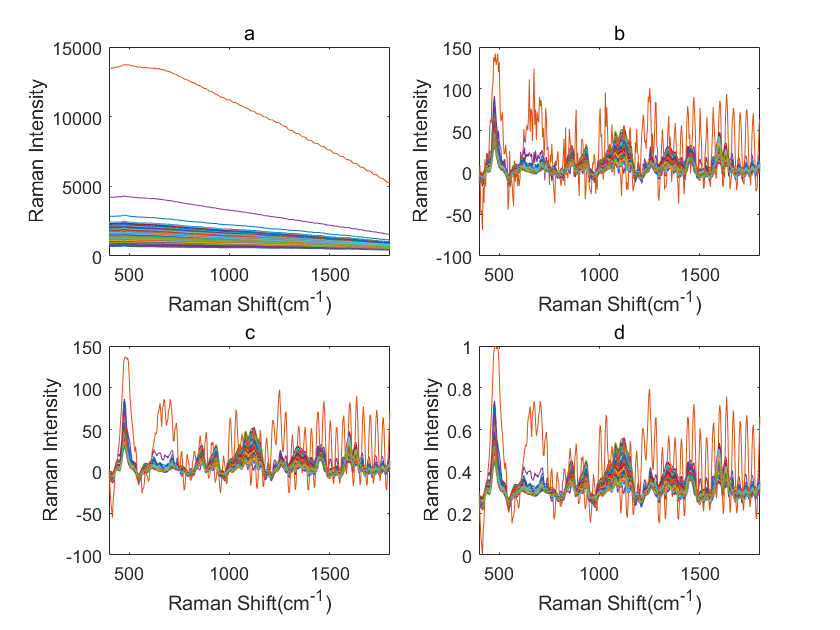

figure;
subplot(2,2,1);
for k = 1:size(X, 1)
    plot(effshift, X_original(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('a')

subplot(2,2,2);
for k = 1:size(X, 1)
    plot(effshift, X_air(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('b')

subplot(2,2,3);
for k = 1:size(X_air_sg, 1)
    plot(effshift, X_air_sg(k, :));
    hold on;
end
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('c')

subplot(2,2,4);
for k = 1:size(X, 1)
    plot(effshift, X_air_sg_01(k, :));
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
title('d')

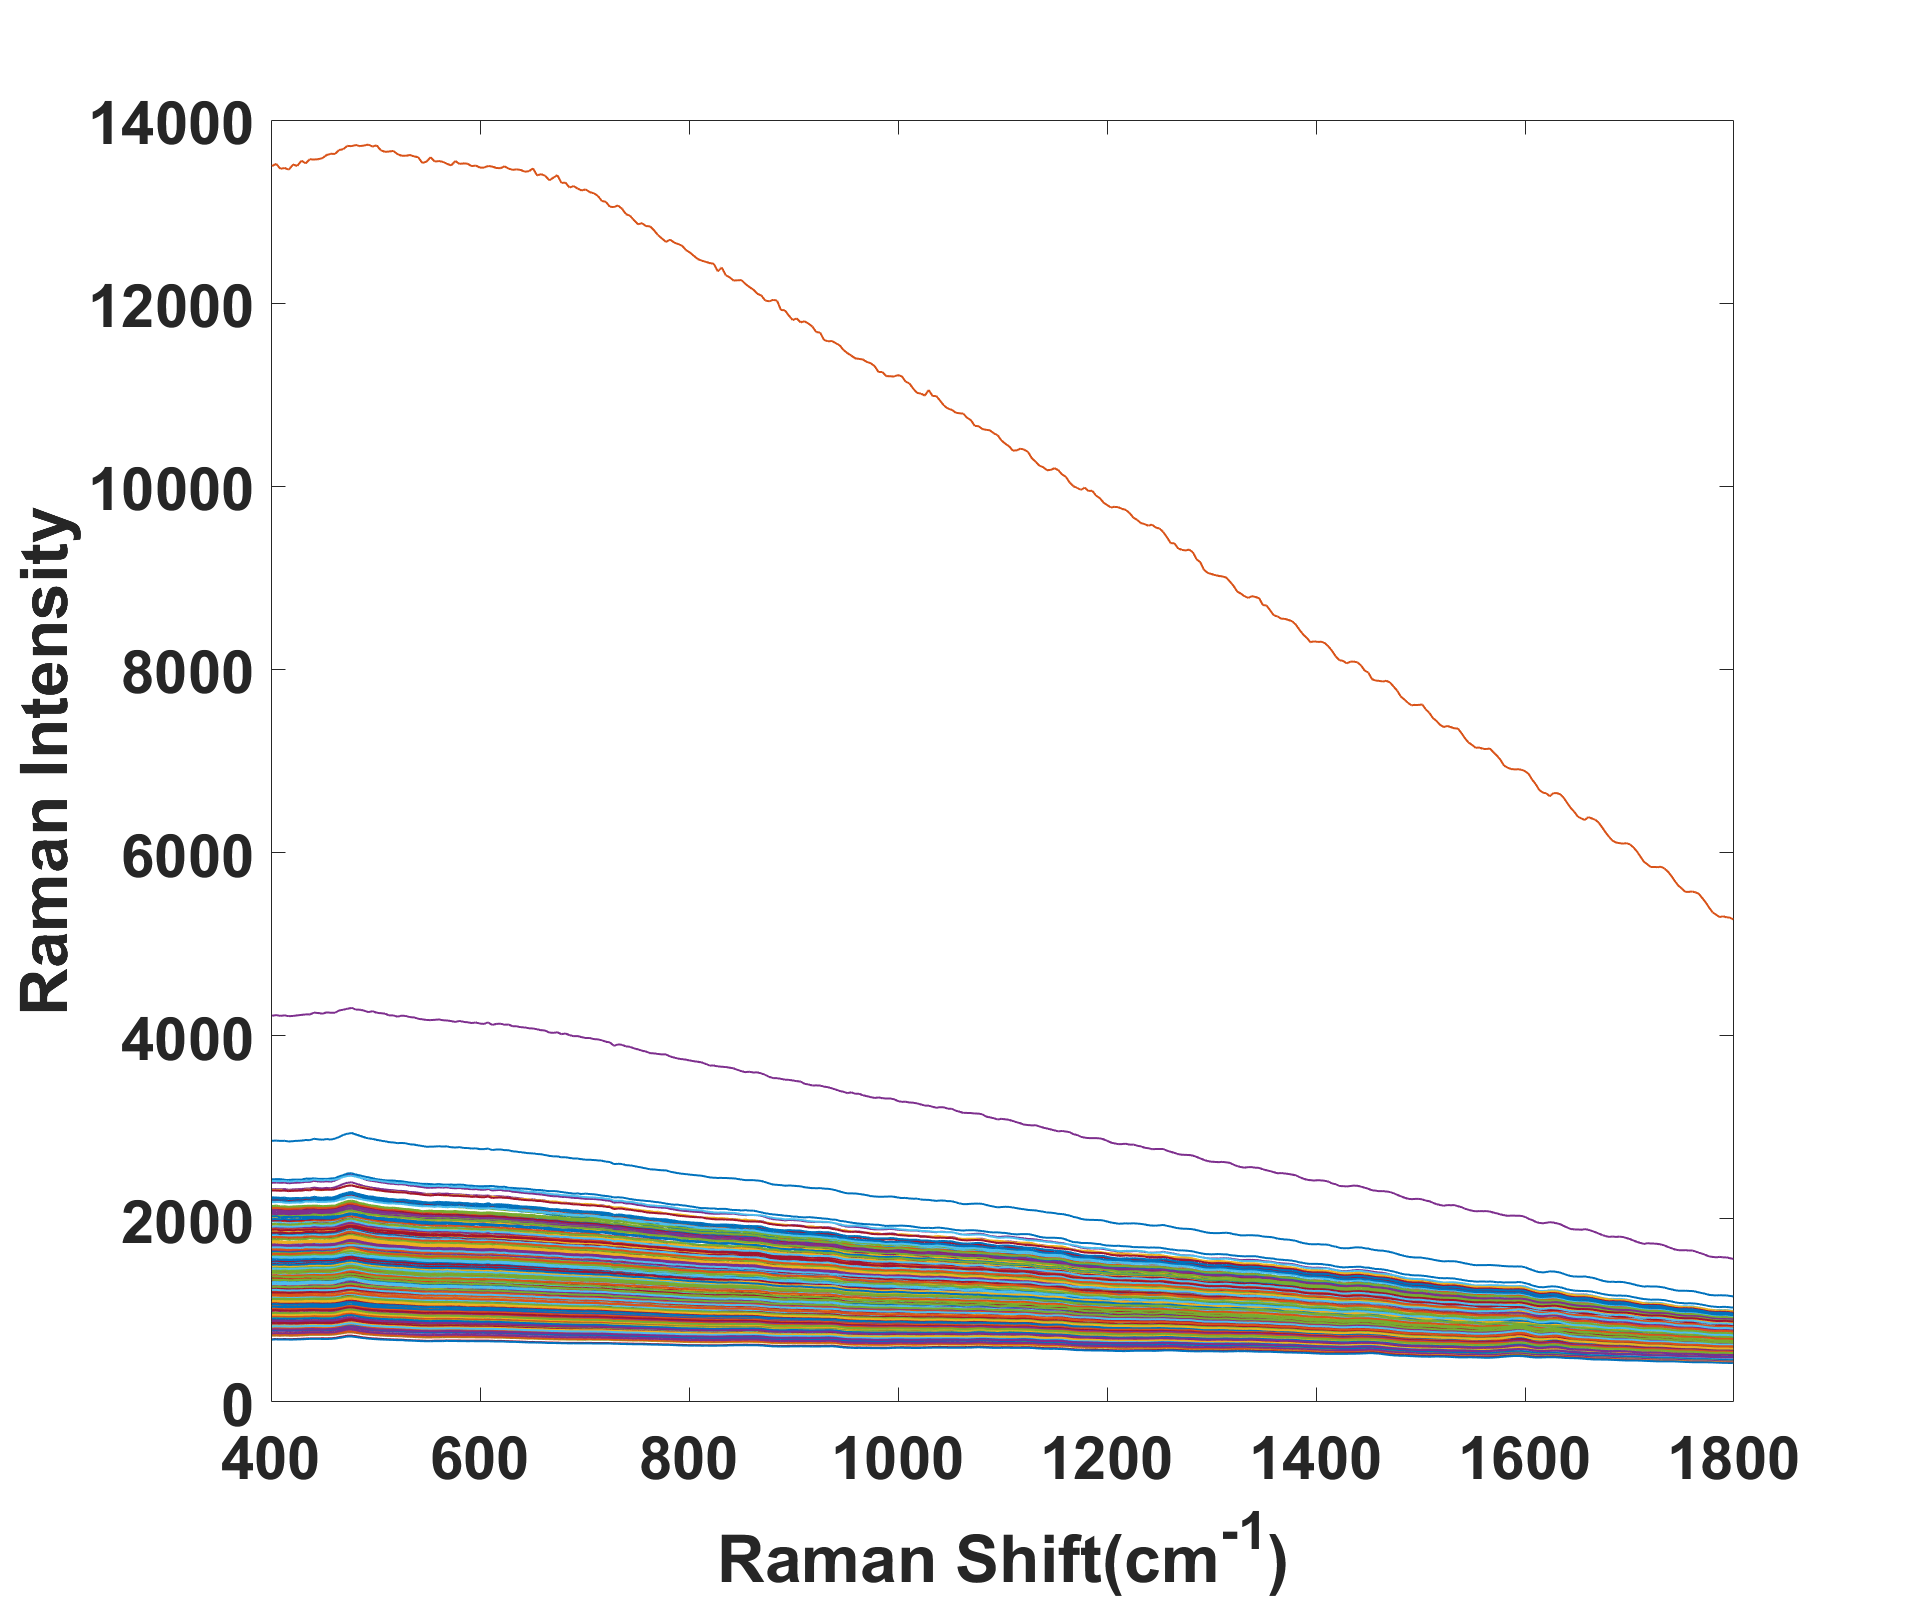

figure('Units','normalized','Position',[0, 0, 0.75, 1]);
for k = 1:size(X_original, 1)
    plot(effshift, X_original(k, :), "LineWidth", 1);
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
set(gca,'fontsize',30, 'FontWeight','bold');

figure('Units','normalized','Position',[0, 0, 0.75, 1]);
for k = 1:size(X_total_original_noout, 1)
    plot(effshift, X_total_original_noout(k, :), "LineWidth", 1);
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
set(gca,'fontsize',45, 'FontWeight','bold');

figure('Units','normalized','Position',[0, 0, 0.75, 1]);
for k = 1:size(X_total_noout, 1)
    plot(effshift, X_total_noout(k, :), "LineWidth", 1);
    hold on;
end 
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
set(gca,'fontsize',30, 'FontWeight','bold');


% X1 = []; 
% y1 = [];
% 
% seed_varieties = ["zd958nc", "zd958"];   %% " "
% file_names = [25, 50, 75, 100];
% 
% for index1 = 1:length(seed_varieties)    
%     seed_variety = seed_varieties(index1);    
%     for index2 = 1:length(file_names)        
%         file_name = file_names(index2);
%         
%         mat_name = char(strcat(seed_variety, '_', num2str(file_name), '_Pre'));
%         data = eval([mat_name, '.avedata_sg_air_snv;']);
%         X1 = [X1; data];
%         y1_incre = ones(25, 1) * (index1 - 1);
%         y1 = [y1; y1_incre];
%     end
% end

% X1_1st = pre_sgfilter(X1, 15, 2, 1);
% X1_2nd = pre_sgfilter(X1, 15, 2, 2);


% sg_data = zeros(size(air_data));
% for k = 1:25
%     sg_data_incre = pre_sgfilter(air_data(k, :), 15, 2, 0);
%     sg_data(k, :) = sg_data_incre;
% end
% 
% figure;
% for k = 1:25
%     plot(effshift, sg_data(k, :));
%     hold on;
% end

% data = X;
% 
% figure('Units','normalized','Position',[0.1, 0.25, 0.8, 0.5]);
% colors = ['r', 'y', 'g', 'b'];
% seed_varieties = ["zd958", "jd20", "nh816", "jh5"];   %% " "
% file_names = [25, 50, 75, 100];
% 
% for index3 = 1:length(seed_varieties)
%     color = colors(index3);
%     for index4 = 1:length(file_names)
%         ii = (index3-1)*25*length(file_names) + (index4-1)*25 + 1;
%         jj = (index3-1)*25*length(file_names) + index4*25;
%         plot(effshift, data(ii:jj, :), "Color", color);
%         hold on;
%     end
% end
% 
% for i = 1:length(vsel)
%     xline(effshift(vsel(i)));
%     hold on;
% end
% 
% title('avedata of 100 seeds after sg&airpls&snv')


y1 = find(y == 1); 
y2 = find(y == 2);
y3 = find(y == 3);
y4 = find(y == 4);

data = X;
avedata_variety = zeros(4, length(effshift));

avedata_variety(1, :) = mean(data(y1, :), 1);
avedata_variety(2, :) = mean(data(y2, :), 1);
avedata_variety(3, :) = mean(data(y3, :), 1);
avedata_variety(4, :) = mean(data(y4, :), 1);

% markline = avedata_variety(1, :)
% [~, mark1] = min(abs(effshift - 477));
% [~, mark2] = min(abs(effshift - 1003));
% [~, mark3] = min(abs(effshift - 1153));
% [~, mark4] = min(abs(effshift - 1518));
% [~, mark5] = min(abs(effshift - 1596));
% [~, mark6] = min(abs(effshift - 1630));
% text(effshift(mark1),markline(mark1), '\leftarrow 477', 'FontSize',15, 'FontWeight','bold')
% text(effshift(mark2),markline(mark2), '\leftarrow 1003', 'FontSize',15, 'FontWeight','bold')
% text(effshift(mark3),markline(mark3), '\leftarrow 1153', 'FontSize',15, 'FontWeight','bold')
% text(effshift(mark4),markline(mark4), '\leftarrow 1518', 'FontSize',15, 'FontWeight','bold')
% text(effshift(mark5),markline(mark5), '\leftarrow 1596', 'FontSize',15, 'FontWeight','bold')
% text(effshift(mark6),markline(mark6), '\leftarrow 1630', 'FontSize',15, 'FontWeight','bold')


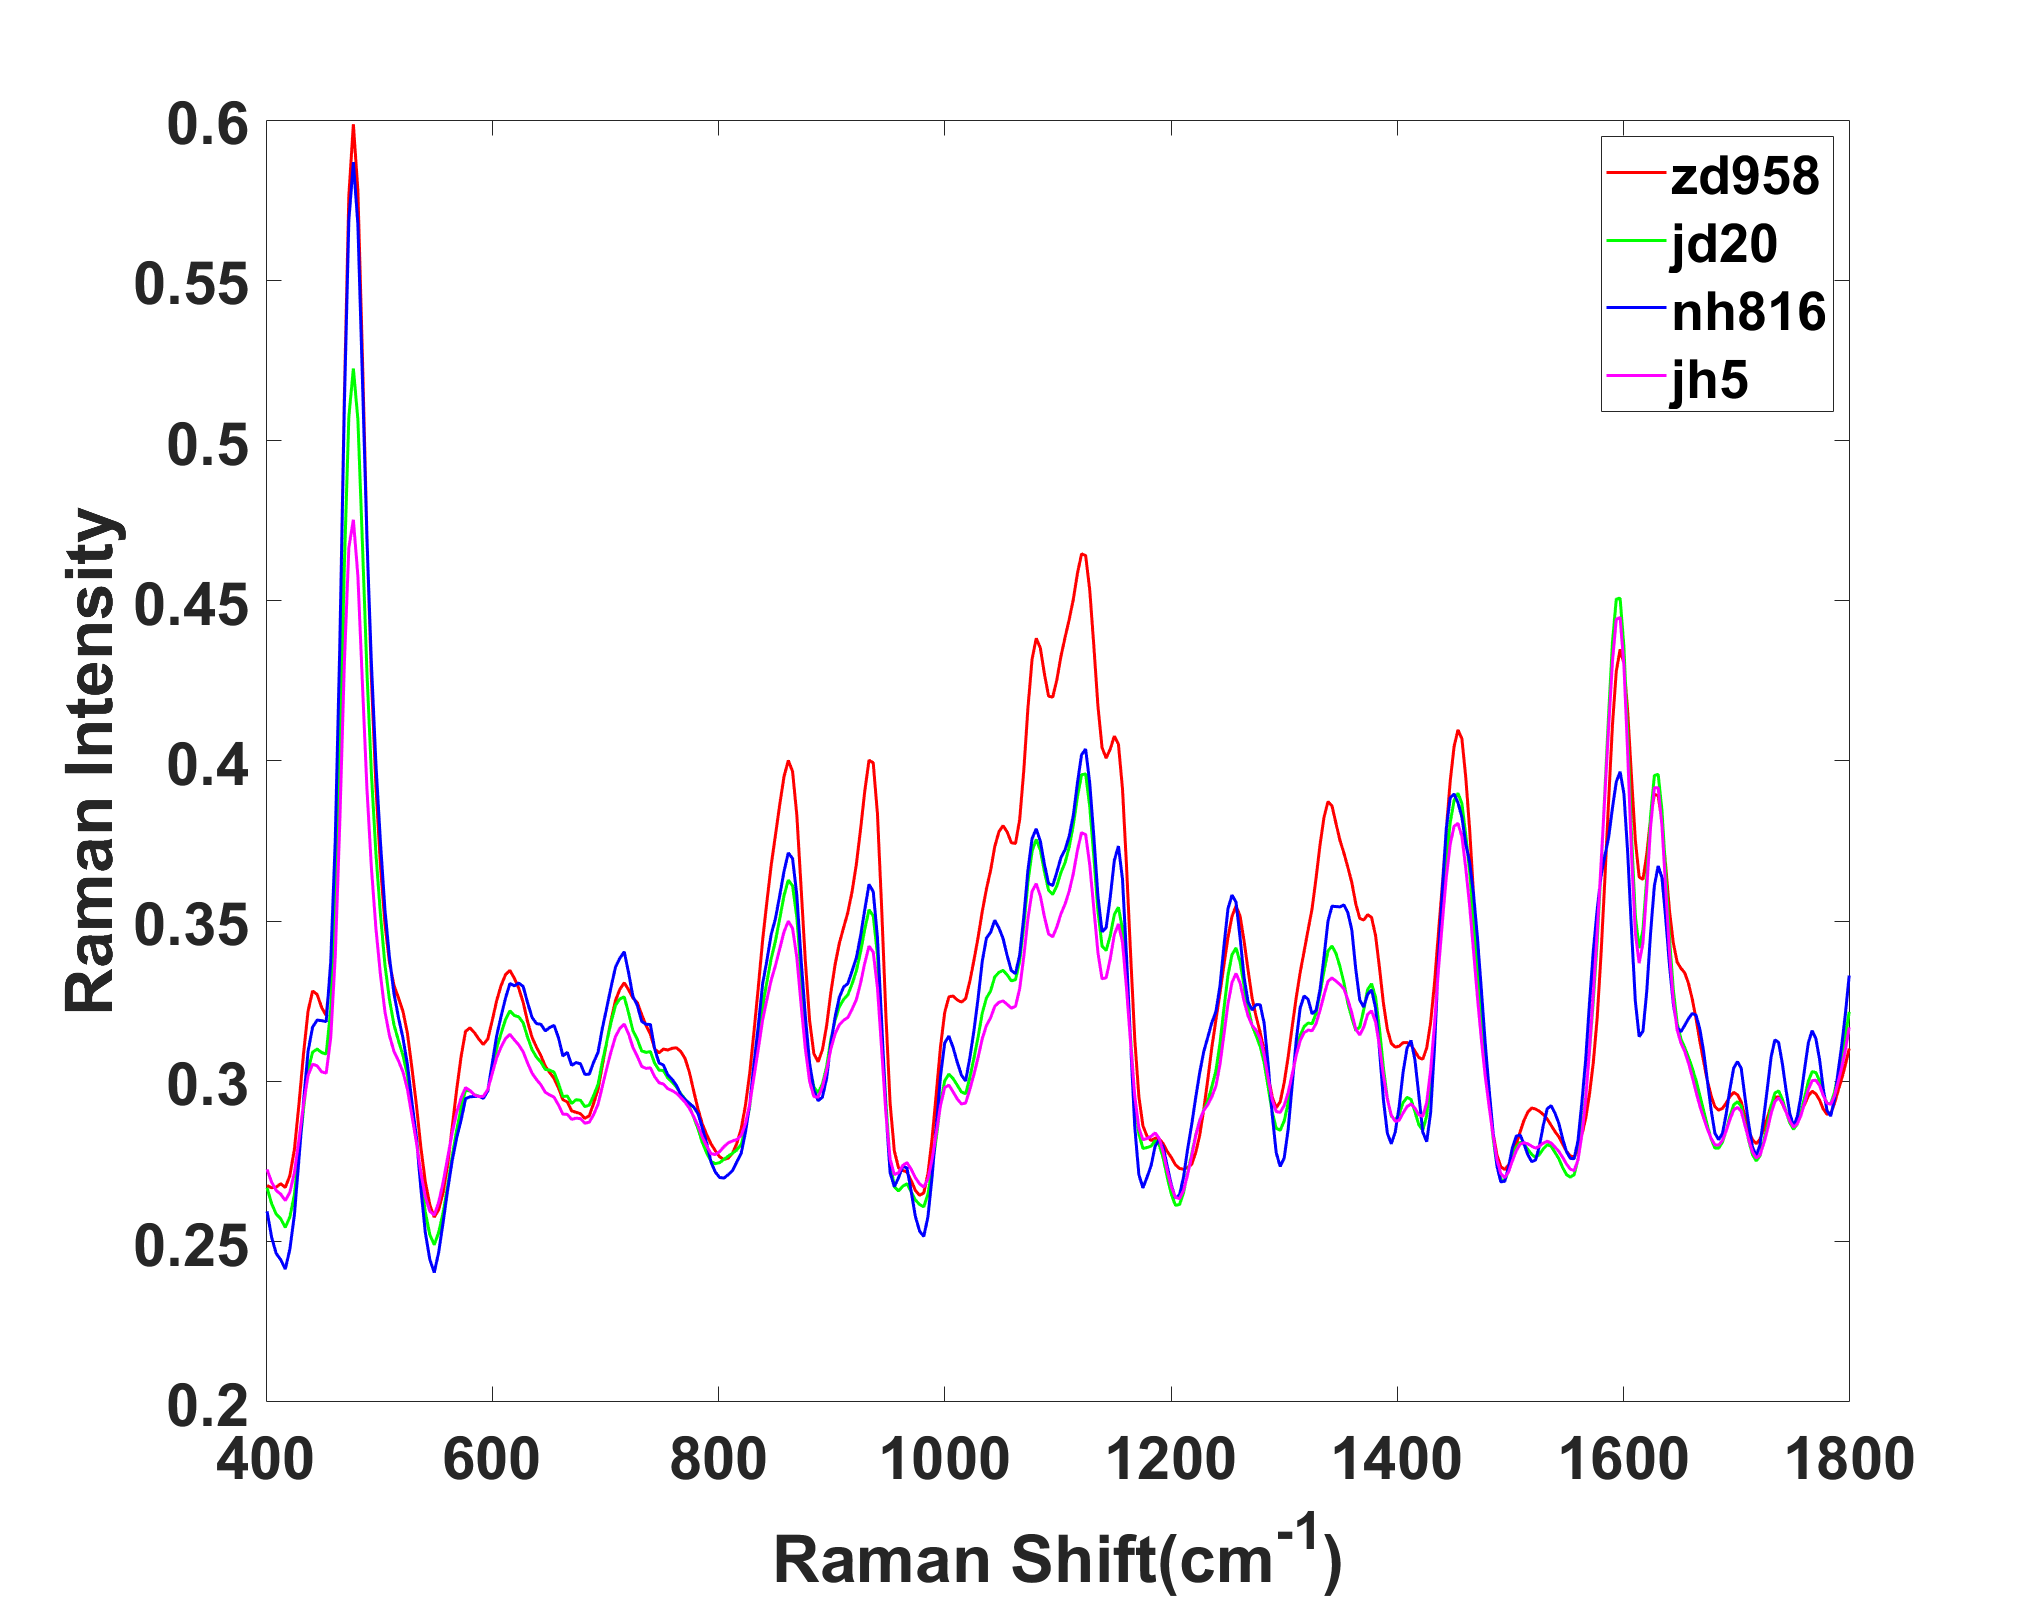

figure('Units','normalized','Position',[0, 0, 0.8, 1]);
seed_varieties = ["zd958", "jd20", "nh816", "jh5"];
colors = ['r', 'g', 'b', 'm'];

for k = 1:length(seed_varieties)
    plot(effshift, avedata_variety(k, :), "Color", colors(k), "LineWidth", 1.5);
    hold on;
end

% for i = 1:length(vsel_spa2)
%     xline(effshift(vsel_spa2(i)));
%     hold on;
% end
xlim([400, 1800])
xlabel('Raman Shift(cm^{-1})')
ylabel('Raman Intensity')
legend(seed_varieties) 
set(gca,'fontsize',30, 'FontWeight','bold');